# **电偶极子天线的方向图演示（利用实时脚本等解析计算）**

**      一般情况下，方向图函数是球坐标系下方位角的函数，即**$$$F\left(\theta,\varphi\right)$$$**。在球坐标系下绘制方向图的时候，可以定义函数**$$$r=F(\theta,\varphi)$$$**，在空间对**$$$\left(r,\theta,\varphi\right)$$$**进行描点，所得曲面即为方向图。在二维情况下，可以使用 MATLAB下的 polar(theta,rho)函数进行方向图绘制。例如对偶极子天线**


$$F(\theta )=\sin \theta$$


**可以定义函数**$$$r=F\left(\theta,\varphi\right)=\mathrm{sin}\theta $$$**，然后在极坐标系下直接绘图。**

- **定义取值范围**

theta=0:pi/100:2*pi;

- **定义方向图函数**

rho=abs(sin(theta));   

- **利用polar函数绘制曲线**

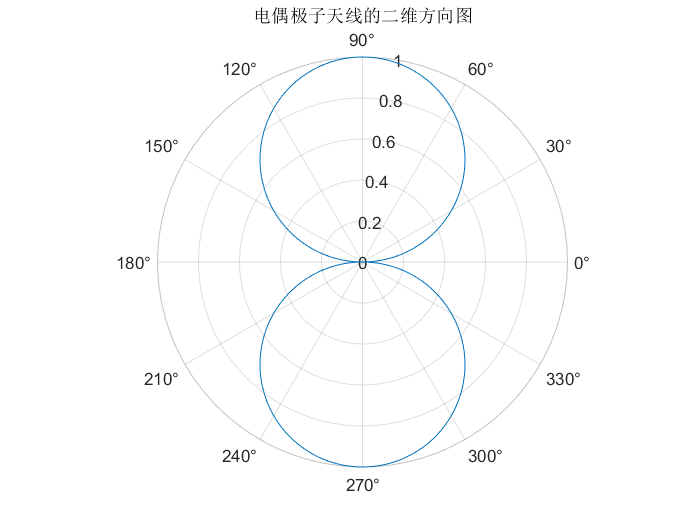

figure(1);
polarplot(theta,rho)
title('电偶极子天线的二维方向图')
set(gcf,'Visible','on');   	    %强制图片弹出显示

- **旋转得到三维方向图**

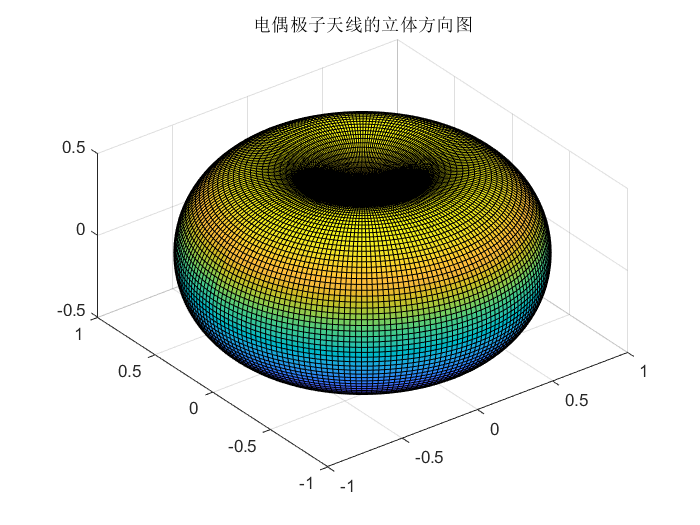

phi=0:pi/100:2*pi;	%phi向量定义
x=(rho.*sin(theta))'*cos(phi);
y=(rho.*sin(theta))'*sin(phi);
z=(rho.*cos(theta))'*ones(size(phi));
figure(2);
surf(x,y,z);                      %绘制曲面
title(['电偶极子天线的立体方向图']);
axis equal;                          %设置各个轴等比例显示
set(gcf,'Visible','on');   	    %强制图片弹出显示